clear, clc

## CORRECT DATA

for i = 1:n_neurons
    neuron(i).bestParams = parametersFinal(i,:);
    neuron(i).bestFactor = neuron(i).err_coincidence_factor(parametersFinal(i,:));
end

## LOAD FINAL PARAMETERS

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters';
names = {'ga_coincidencefactor_conductancebetaQ','ga_coincidencefactor_justconductances',...
    'ga_coincidencefactor_all','ga_coincidencefactor_bestparameters'};
n_data = length(names);

for i = 1:n_data
    data(i) = load([path '\' names{i} '.mat']);
end
clear path, clear names, clear i

## PLOT THE COMPARISON IN FACTOR BETWEEN MODELS AND OPTIMIZATION ALGORITHMS

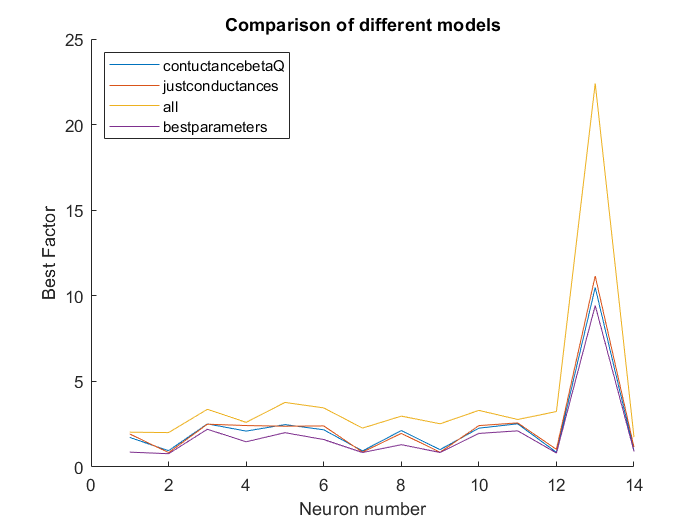

neuron_num = 1:size(data(1).parametersFinal,1);
bestFactor_vec = zeros(1,size(data(1).parametersFinal,1));

figure, clf, hold on
for i = 1:n_data
    for MNIndex = neuron_num
        bestFactor_vec(MNIndex) = data(i).Neuron(MNIndex).bestFactor;
    end
    plot(neuron_num,bestFactor_vec)
    names_legend{i} = data(i).model;
end
xlabel('Neuron number')
ylabel('Best Factor')
title('Comparison of different models')
legend(names_legend,'Location','northwest')